# Lab 1: Fourier Series

[⇦ Fourier Analysis Overview](matlab: OpenOverview)

**1. **Consider the Fourier sine series:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left(  2 \pi    t \right)$$


Open the [Sine and Cosine Series app](matlab: SinCosSeries). Set the basis to **sine**. Adjust the coefficients to determine the values of $b_2$ and $b_4$ that generate the function $f$ pictured below. Round to the nearest 0.5 and record your answer below. The other coefficients are zero.

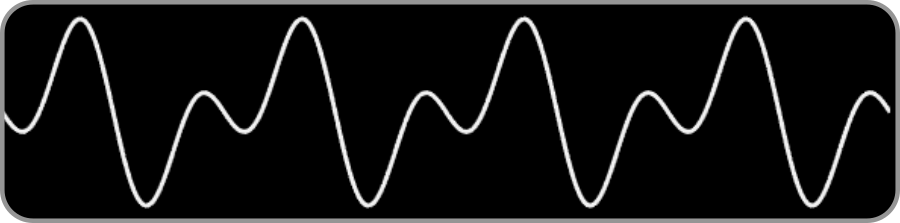

% Replace the NaNs with your answers
Q1_b2 = 1;
Q1_b4 = -1;

**2. **Consider the phase-shifted cosine:


$$g(t) = 1.4\cos(4 \pi t  - \pi/4 )$$


Use the [Magnitude and Phase app](matlab: run MagnitudePhase.mlapp) to recreate the function using Fourier series.

**a.** Use the magnitude-phase definition (right pane). What are the values of $A_2$ and $\phi_2$ that recreate the function?

Q2_A2 = 1.4;
Q2_phi2 = pi/4;

**b.** Use the sine-cosine definition (left pane). What are the values of $a_2$ and $b_2$ that recreate the function? Round to the nearest tenth.

Q2_a2 = 1;
Q2_b2 = 1;

**Task.** Q3-5 use data from an audio signal. Run this section to load the data and compute its Fourier series coefficients.

[y,Fs] = audioread("SynthesizedSound.mp4"); % Read the data
sound(y,Fs) % Play the sound
plot(y) % Plot the data
ylabel("y")
[freq,a,b] = computeFourierCoef(y',Fs); % Compute series coef.

**3. **Compute the magnitude and phase of the Fourier coefficients, which are stored in vectors `a` and `b`. Store the results in `A` and `phi`.

**Hint:** Use [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html) to compute the phase.

A = sqrt(a.^2 + b.^2);
phi = atan2(b,a);

**4. **Plot the magnitude vector `A` against the frequency vector `freq`, which is given in units of Hz. Set the horizontal axis limits to `[0 200]` Hz. Also, label the axes.

% Write your code here
plot(freq,A)
xlim([0 200])
xlabel("Frequency (Hz)")
ylabel("Magnitude")

**5. **There are several distinct peaks in the frequency domain. What are the frequencies of the peaks in Hz?

% Record your answers in the vector freqPeaks
% e.g., freqPeaks = [2 5 10]
freqPeaks = [100 120 150];

**6.** Create an audio signal of the form


$$x(t) = \sum_{n=1}^3 b_n \sin\left(2 \pi f_n t\right)$$


with only three terms: the frequencies of the peaks you identified in the audio signal in **5**. Set the coefficient of the highest frequency to 0.1 and the coefficient of the two lower frequencies to 0.2.

Define your signal `x` in terms of the variable `t`. 

t = 0:1/Fs:3; % Use this variable
% Write your code here
x = 0.1*sin(2*pi*150*t) + 0.2*sin(2*pi*120*t) + 0.2*sin(2*pi*100*t);

**7.** Plot the signal $x$ against $t$. 

plot(t,x)
xlabel("t (s)")
ylabel("x")

**8. **Play the signal $x$ as an audio sound using the [`sound`](https://www.mathworks.com/help/matlab/ref/sound.html) function.

sound(x,Fs)

**9. **Compute the Fourier coefficients of `x` by uncommenting the line below. Then, compute the magnitude of the coefficients. Store the value in `Ax`.

[freq,a,b] = computeFourierCoef(x,Fs);
Ax = sqrt(a.^2 + b.^2);

**10. **Plot the magnitude vector `A` against the frequency vector `freq`, which has units of Hz. Set the horizontal axis limits to `[0 200]` Hz.

plot(freq,Ax)
xlim([0 200])
xlabel("Frequency (Hz)")
ylabel("Magnitude")

**11.** Compare original signal $y$ to the signal $x$ you created using only three frequencies. 

- What similarity(ies) do you notice between the two signals? 

- What is the main difference between them?

% Record your answers below in the quotes.
similarity = "Similar frequency content."
difference = "No amplitude modulation in x(t)."

[⇦ Fourier Analysis Overview](matlab: OpenOverview)

function [freq,a,b] = computeFourierCoef(y,Fs)
% This helper function computes the Fourier coefficients
% of a signal y(t) with sampling frequency Fs

    % FFT
    Y = fft(y);

    % Fourier series coefficients from the FFT
    N = numel(y);
    Nterms = round(N/2);
    YHalf = Y(2:Nterms);
    a0 = real(Y(1))/N;
    a = [a0,2/N*real(YHalf)];
    b = [0,-2/N*imag(YHalf)];

    % The frequencies of the coefficients
    freq = Fs/N*(0:(Nterms-1))';
end
